# **Implementation of the Partial Least Squares (PLS) algorithm for classification**

Runnable example of how *PLS.m*, i.e. the class that implements the Partial Least Squares algorithm, can be use to perform fault diagnosis. In particular, the example in this script deals with steel plates: starting from $27$ variables, we want to train a PLS models (simplified thanks to the *order reduction*) that it is able to predict the fault classes.

#### 1. Data import

clc
clearvars
warning off

data = readtable("..\Data\Sources\stell-faults.csv");
faultClasses = data.Properties.VariableNames;
faultClasses = faultClasses(28:end);
rowLimits = [158 348 739 811 866 1268 size(data, 1)];
colLimits = 28:size(data, 2);

#### 2. Preliminary analysis: choice of *p *through test CV MCE

% PLS2
nIter = 10;
for nVar = 2:length(faultClasses)
    disp("p = " + nVar)
    subset = data(1:rowLimits(nVar), 1:colLimits(nVar));
    X = subset{1:rowLimits(nVar), 1:28};
    Y = subset{1:rowLimits(nVar), faultClasses(1:nVar)};
    mhat2 = PLS(X, Y, true, 28, false);
    mhat2 = mhat2.orderAnalysis(10);
    if nVar == 2
        figure
        plot(mhat2.orderRed.MCE_statistics.Avg*100, '-', 'LineWidth', 1.5)
        xlim([0 size(X, 2)+1])
    else
        hold on
        grid on
        plot(mhat2.orderRed.MCE_statistics.Avg*100, '-', 'LineWidth', 1.5)
    end
end

p = 2
p = 3
p = 4
p = 5
p = 6
p = 7


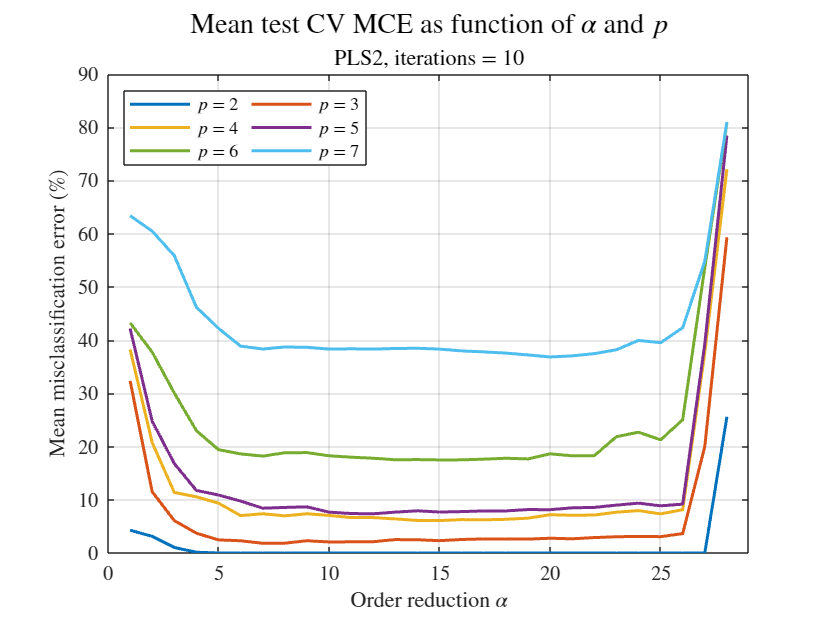

xlabel("Order reduction $\alpha$", 'Interpreter', 'latex');
ylabel("Mean misclassification error (\%)", 'Interpreter', 'latex');
ax = gca;
ax.XAxis.TickLabelInterpreter = 'latex';
ax.YAxis.TickLabelInterpreter = 'latex';
leg = repmat("$p$ = ", 1, length(faultClasses)-1) + (2:length(faultClasses));
legend(leg, 'Interpreter', 'latex', 'Orientation', 'horizontal',...
    'Location', 'northwest', 'NumColumns', 2)
title("Mean test CV MCE as function of $\alpha$ and $p$", 'FontSize', 14, 'Interpreter', 'latex')
subtitle("PLS2, iterations = " + nIter, 'Interpreter', 'latex')

% PLS1
for nVar = 2:length(faultClasses)
    disp("p = " + nVar)
    subset = data(1:rowLimits(nVar), 1:colLimits(nVar));
    X = subset{1:rowLimits(nVar), 1:28};
    Y = subset{1:rowLimits(nVar), faultClasses(1:nVar)};
    mhat1 = PLS(X, Y, false, 28, false);
    mhat1 = mhat1.orderAnalysis(10);
    if nVar == 2
        figure
        plot(mhat1.orderRed.MCE_statistics.Avg*100, '-', 'LineWidth', 1.5)
        xlim([0 size(X, 2)+1])
    else
        hold on
        grid on
        plot(mhat1.orderRed.MCE_statistics.Avg*100, '-', 'LineWidth', 1.5)
    end
end

p = 2
p = 3
p = 4
p = 5
p = 6
p = 7


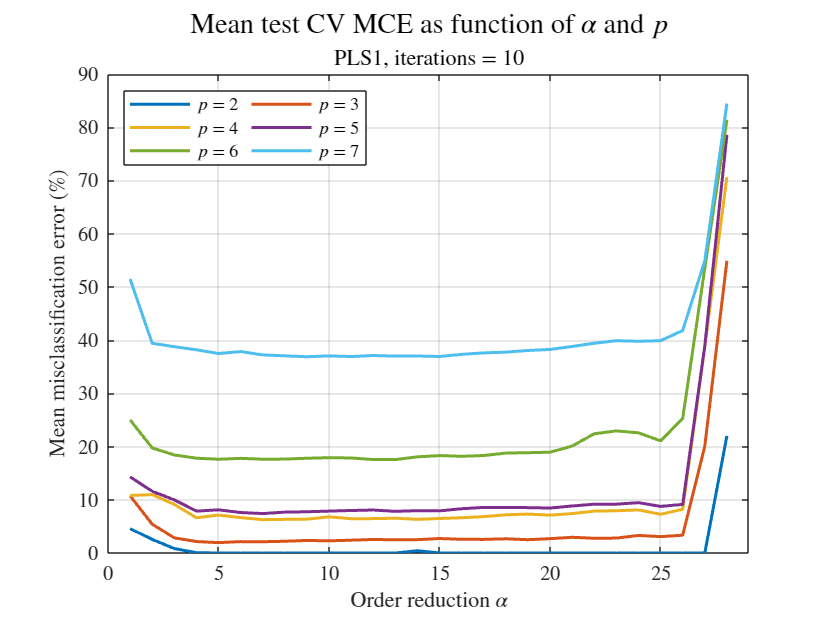

xlabel("Order reduction $\alpha$", 'Interpreter', 'latex');
ylabel("Mean misclassification error (\%)", 'Interpreter', 'latex');
ax = gca;
ax.XAxis.TickLabelInterpreter = 'latex';
ax.YAxis.TickLabelInterpreter = 'latex';
leg = repmat("$p$ = ", 1, length(faultClasses)-1) + (2:length(faultClasses));
legend(leg, 'Interpreter', 'latex', 'Orientation', 'horizontal',...
    'Location', 'northwest', 'NumColumns', 2)
title("Mean test CV MCE as function of $\alpha$ and $p$", 'FontSize', 14, 'Interpreter', 'latex')
subtitle("PLS1, iterations = " + nIter, 'Interpreter', 'latex')

#### 3. Identification of the best order reduction through test CV MCE

nIter = 50;
nVar = 5;
subset = data(1:rowLimits(nVar), 1:colLimits(nVar));
X = subset{1:rowLimits(nVar), 1:28};
Y = subset{1:rowLimits(nVar), faultClasses(1:nVar)};

% PLS2
model2 = PLS(X, Y, true);

PLS configuration: 
- PLS2: true
- Normalization: true
- Maximum iterations: 1000
- Tolerance: 1e-10
- Num. of output variables: 5
- Num. of input variables: 28
- Order reduction: 28


model2 = model2.orderAnalysis(nIter, true);

Iteration 1 of 50, order 1 of 28 (0.07%)
Iteration 1 of 50, order 2 of 28 (0.14%)
Iteration 1 of 50, order 3 of 28 (0.21%)
Iteration 1 of 50, order 4 of 28 (0.29%)
Iteration 1 of 50, order 5 of 28 (0.36%)
Iteration 1 of 50, order 6 of 28 (0.43%)
Iteration 1 of 50, order 7 of 28 (0.5%)
Iteration 1 of 50, order 8 of 28 (0.57%)
Iteration 1 of 50, order 9 of 28 (0.64%)
Iteration 1 of 50, order 10 of 28 (0.71%)
Iteration 1 of 50, order 11 of 28 (0.79%)
Iteration 1 of 50, order 12 of 28 (0.86%)
Iteration 1 of 50, order 13 of 28 (0.93%)
Iteration 1 of 50, order 14 of 28 (1%)
Iteration 1 of 50, order 15 of 28 (1.07%)
Iteration 1 of 50, order 16 of 28 (1.14%)
Iteration 1 of 50, order 17 of 28 (1.21%)
Iteration 1 of 50, order 18 of 28 (1.29%)
Iteration 1 of 50, order 19 of 28 (1.36%)
Iteration 1 of 50, order 20 of 28 (1.43%)
Iteration 1 of 50, order 21 of 28 (1.5%)
Iteration 1 of 50, order 22 of 28 (1.57%)
Iteration 1 of 50, order 23 of 28 (1.64%)
Iteration 1 of 50, order 24 of 28 (1.71%)
Iterat

% PLS1
model1 = PLS(X, Y, false);

PLS configuration: 
- PLS2: false
- Normalization: true
- Maximum iterations: 1000
- Tolerance: 1e-10
- Num. of output variables: 5
- Num. of input variables: 28
- Order reduction: 28


model1 = model1.orderAnalysis(nIter, true);

Iteration 1 of 50, order 1 of 28 (0.07%)
Iteration 1 of 50, order 2 of 28 (0.14%)
Iteration 1 of 50, order 3 of 28 (0.21%)
Iteration 1 of 50, order 4 of 28 (0.29%)
Iteration 1 of 50, order 5 of 28 (0.36%)
Iteration 1 of 50, order 6 of 28 (0.43%)
Iteration 1 of 50, order 7 of 28 (0.5%)
Iteration 1 of 50, order 8 of 28 (0.57%)
Iteration 1 of 50, order 9 of 28 (0.64%)
Iteration 1 of 50, order 10 of 28 (0.71%)
Iteration 1 of 50, order 11 of 28 (0.79%)
Iteration 1 of 50, order 12 of 28 (0.86%)
Iteration 1 of 50, order 13 of 28 (0.93%)
Iteration 1 of 50, order 14 of 28 (1%)
Iteration 1 of 50, order 15 of 28 (1.07%)
Iteration 1 of 50, order 16 of 28 (1.14%)
Iteration 1 of 50, order 17 of 28 (1.21%)
Iteration 1 of 50, order 18 of 28 (1.29%)
Iteration 1 of 50, order 19 of 28 (1.36%)
Iteration 1 of 50, order 20 of 28 (1.43%)
Iteration 1 of 50, order 21 of 28 (1.5%)
Iteration 1 of 50, order 22 of 28 (1.57%)
Iteration 1 of 50, order 23 of 28 (1.64%)
Iteration 1 of 50, order 24 of 28 (1.71%)
Iterat

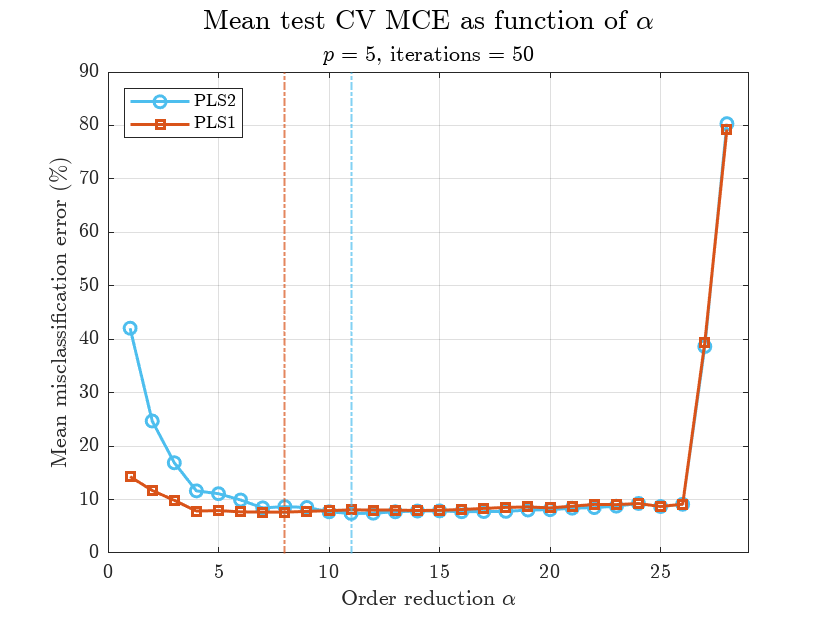

% results plotting
figure
plot(model2.orderRed.MCE_statistics.Avg*100, '-o', 'LineWidth', 1.5, 'Color', '#4DBEEE')
xlim([0 model2.mX+1])
hold on
grid on
plot(model1.orderRed.MCE_statistics.Avg*100, '-square', 'LineWidth', 1.5, 'Color', '#D95319')
xline(model2.orderRed.bestAlpha, '-.', 'Color', '#4DBEEE', 'LineWidth', 1)
xline(model1.orderRed.bestAlpha, '-.', 'Color', '#D95319', 'LineWidth', 1)
xlabel('Order reduction $\alpha$', 'Interpreter', "latex")
ylabel('Mean misclassification error (\%)', 'Interpreter', 'latex')
ax = gca;
ax.XAxis.TickLabelInterpreter = 'latex';
ax.YAxis.TickLabelInterpreter = 'latex';
legend("PLS2", "PLS1", 'Interpreter', 'latex', 'location', 'northwest');
title("Mean test CV MCE as function of $\alpha$", 'Interpreter', 'latex', ...
    'FontSize', 14)
subtitle("$p$ = " + nVar + ", iterations = " + nIter, 'Interpreter', 'latex')

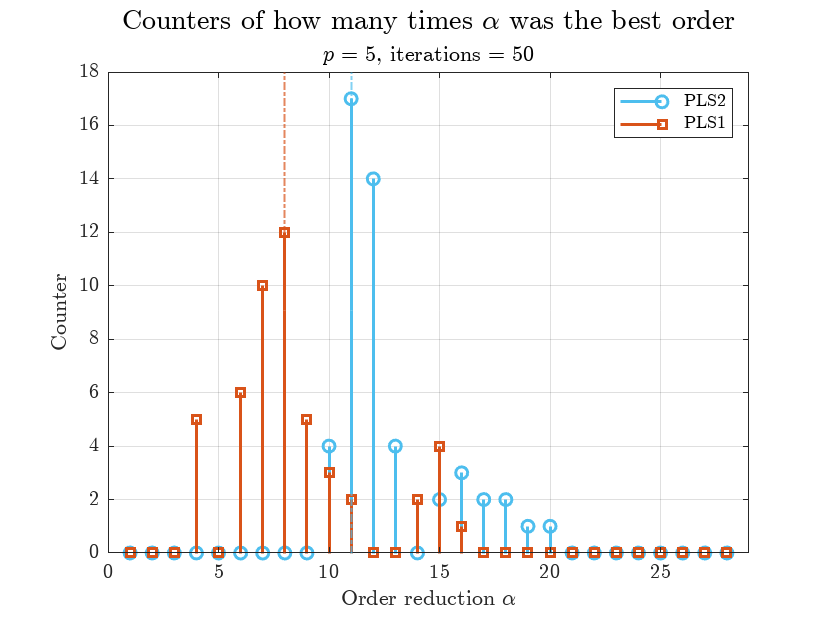

figure
stem(model2.orderRed.bestAlphaCounters.Counter, 'o', 'LineWidth', 1.5, 'Color', '#4DBEEE')
xlim([0 model2.mX+1])
hold on
grid on
stem(model1.orderRed.bestAlphaCounters.Counter, 'square', 'LineWidth', 1.5, 'Color', '#D95319')
xline(model2.orderRed.bestAlpha, '-.', 'Color', '#4DBEEE', 'LineWidth', 1)
xline(model1.orderRed.bestAlpha, '-.', 'Color', '#D95319', 'LineWidth', 1)
xlabel('Order reduction $\alpha$', 'Interpreter', "latex")
ylabel('Counter', 'Interpreter', 'latex')
ax = gca;
ax.XAxis.TickLabelInterpreter = 'latex';
ax.YAxis.TickLabelInterpreter = 'latex';
legend("PLS2", "PLS1", 'Interpreter', 'latex', 'location', 'northeast');
title("Counters of how many times $\alpha$ was the best order", 'Interpreter', 'latex', ...
    'FontSize', 14)
subtitle("$p$ = " + nVar + ", iterations = " + nIter, 'Interpreter', 'latex')

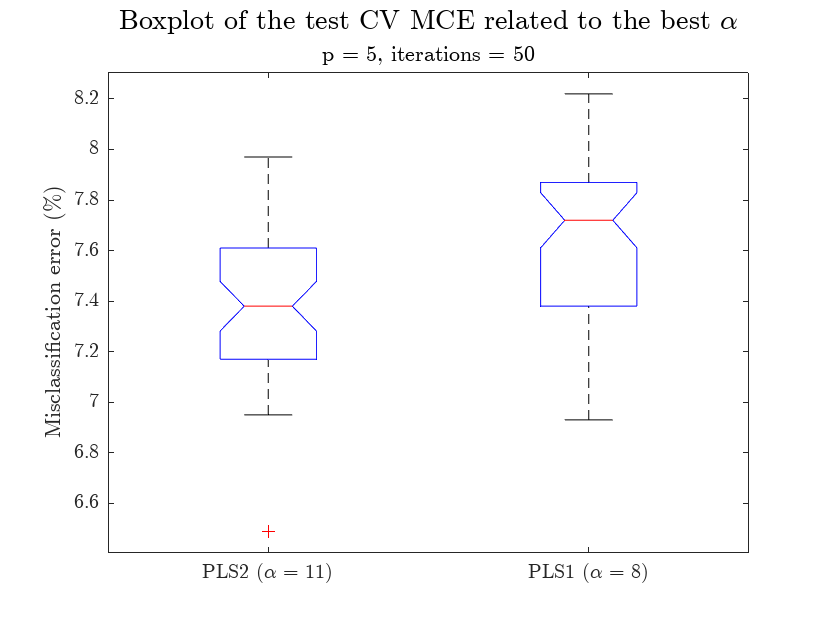

figure
bestAlphaMCE = array2table(zeros(nIter, 2));
bestAlphaMCE.Properties.VariableNames = ["PLS2", "PLS1"];
bestAlphaMCE.PLS2 = round(model2.orderRed.alphaMCE{model2.orderRed.bestAlpha, :}*100, 2)';
bestAlphaMCE.PLS1 = round(model1.orderRed.alphaMCE{model1.orderRed.bestAlpha, :}*100, 2)';
boxplot(bestAlphaMCE{:, :}, 'Labels', {'PLS2 ($\alpha$ = 11)', 'PLS1 ($\alpha$ = 8)'},...
    'Notch', 'on')
ylabel('Misclassification error (\%)', 'Interpreter', 'latex')
ax = gca;
ax.XAxis.TickLabelInterpreter = 'latex';
ax.YAxis.TickLabelInterpreter = 'latex';
title("Boxplot of the test CV MCE related to the best $\alpha$", 'Interpreter', 'latex',...
    'FontSize', 14)
subtitle("p = " + nVar + ", iterations = " + nIter, 'Interpreter', 'latex')